M = [2 0; 0 1]; K = [3000 -1000; -1000 1000]; C = [6 -2; -2 2];
% Eigenvalue solution
[vec,val] = eig(M\K);
nmodes= 2;
% Sort eigenvalues / vectors into ascending order of frequency
% and find natural frequencies and mode shapes (psi is modal matrix)
for j = 1:nmodes
  [max_vec, max_index] = max(abs(vec(:,j))); vec(:,j) = vec(:,j)./vec(max_index,j);
  
  f_nat(j) = sqrt(val(j,j)) / 2 / pi;
end
[f_nat, index] = sort(f_nat);
for j = 1:nmodes
  psi(:,j) = vec(:,index(j));
end
% Modal matrices
MP = psi * M * psi; CP = psi * C * psi; KP = psi * K * psi;
% Modal masses and dampings
for j = 1:nmodes
  modal_mass(j) = MP(j,j); modal_damping(j) = CP(j,j) / 2 / sqrt(MP(j,j) * KP(j,j));
  
end
% Write out results
f_nat, psi, MP, CP, KP, modal_mass, modal_damping

f_nat =     3.5588    7.1176


psi =     0.5000    1.0000
    1.0000   -1.0000


MP =     1.5000         0
         0    3.0000


CP =     1.5000         0
         0   12.0000


KP =          750           0
           0        6000


modal_mass =     1.5000    3.0000


modal_damping =     0.0224    0.0447


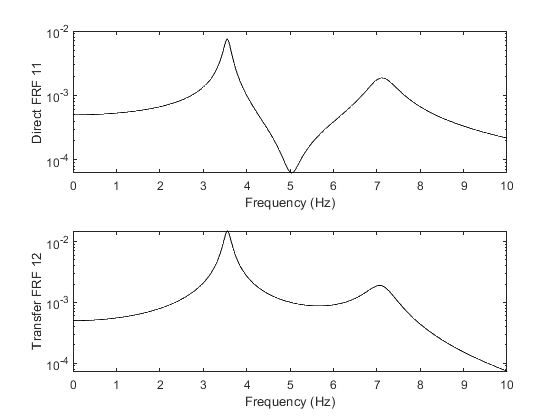

% Set up parameters for FRF generation and initialise FRF matrix
f_nyq = 10; nt = 1024; nf = nt/2 + 1; frq = linspace(0,f_nyq,nf);
H = zeros(nmodes,nmodes,nf);
% Calculate FRF for each frequency value from DC up to Nyquist
% and set Nyquist frequency value to be real - note that FRF needs to
% be a 3 dimensional array (response r / excitation e / fre-
%quency nf)
for ifq = 1:nf
  w = 2 * pi *  frq(ifq);
  H(:,:,ifq) = inv(K - (w^2 * M) + (1i * w *  C));
end
H(:,:,nf) = real(H(:,:,nf));
% Plot first row of FRF matrix - ‘squeeze’ function needed to bring
  %matrix
% from 3 to 2 dimensions in order to plot - use ‘log’ plot to show
%FRF more clearly
subplot(211)
semilogy(frq(1:nf), abs(squeeze(H(1,1,1:nf))),'k');
xlabel('Frequency (Hz)'); ylabel('Direct FRF 11');
subplot(212)
semilogy(frq(1:nf), abs(squeeze(H(1,2,1:nf))),'k');
xlabel('Frequency (Hz)');    ylabel('Transfer FRF 12');